# Introduction to neural networks: shallow neural networks

## Shallow neural networks

Now that we constructed a logistic regression model that performs forward and backward propagation, let's return back to the original model we wanted to build - the neural network with 1 hidden layer. We'll set the number of nodes in the hidden layer equal to 2. 

The schematic for the model we're training and a summary of the computations performed is shown below:

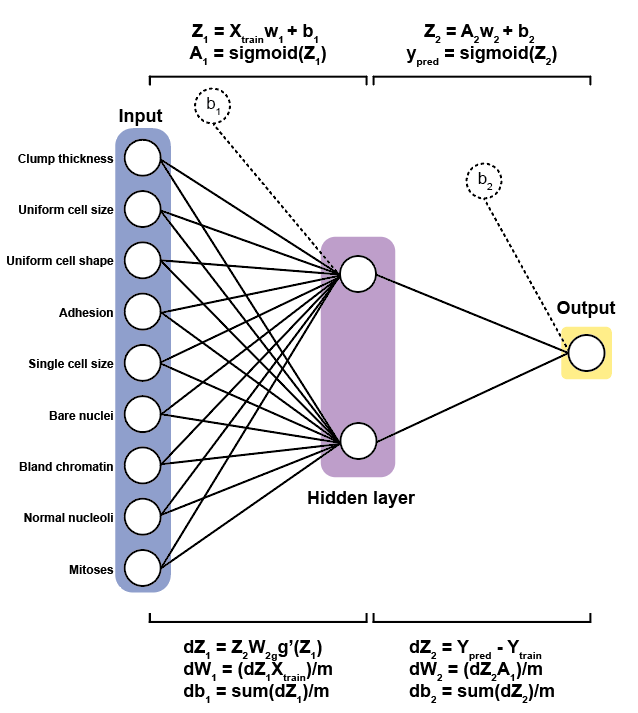

### Load breast cancer imaging dataset

First, let's load the breast cancer imaging dataset we used in the previous section.

clear all; rng(2);
load cancer_dataset.mat

% Initialize params for trainTestSplit
trainingSize = 0.8; randomstate = 2;

% Split the dataset into training and test sets.
[Xtrain, Ytrain, Xtest, Ytest] = ...
    trainTestSplit(cancerInputs', cancerTargets(1, :)', ...
    trainingSize, randomstate);

% Standardize the dataset with mean = 0 and standard deviation = 1. 
mu = mean(Xtrain); sigma = std(Xtrain);
Xtrain = (Xtrain - mu) ./ sigma; 
Xtest  = (Xtest - mu)  ./ sigma; % Use the same mu and sigma -> assume same distribution

### Forward propagation

First let's initialize some parameters and hyperparameters. This time, we'll have 4 parameters to compute: weights and biases between input and hidden layer `(w1, b1)`, and weights / biases between hidden and output layer `(w2, b2)`. 

% Intialize the hyperparameters 
numberOfHiddenNodes = 2; actFnc = 'Sigmoid';

% Intialize the weights and biases. 
w1 = randn([size(Xtrain, 2), numberOfHiddenNodes]) % Size of w1 should be number of features x number of hidden nodes
b1 = randn(size(Xtrain, 1), 1)                     % Size should be number of obs x 1

#### First forward step from the input layer to the hidden layer

Note that Z1 and A1 are the linear combination of features and transformed features. Because we have 2 activation nodes, we have 2 engineered features.

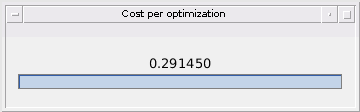

model = struct with fields:
     ypred: [559×1 double]
         J: [500×1 double]
        w2: [2×1 double]
        b2: [559×1 double]
        w1: [9×2 double]
        b1: [559×1 double]
    actFnc: 'Sigmoid'


Z1 = Xtrain * w1 + b1

A1 = activationFnc(Z1, actFnc)

#### The last forward step from the hidden layer to the output layer

Now that we have the transformed values stored in `A1`, we'll use this data and transform it 1 more time using forward propagation. 

First, let's initialize the weights and biases. Note that because we're trying to output a single vector of predicted values, the column size of the weights must also be the same size as Ytrain.

w2 = randn([size(A1, 2), size(Ytrain, 2)]) % Size of w2 needs to be number of features in A1 x number of classes
b2 = randn(size(A1, 1), 1)                 % Size of b2 needs to be number of obs x 1

Finally, let's move 1 forward step from the hidden layer to the output layer. We'll use the same activation function we used in the previous step.

Z2 = A1 * w2 + b2

Because this is the last step, the final transformed dataset is our predicted value `ypred`

ypred = activationFnc(Z2, actFnc)

 That's forward propagation with 1 hidden layer. Next, we need to evaluate the cost.

### Cost evaluation

To evaluate the cost, let's use the cross entropy loss function.

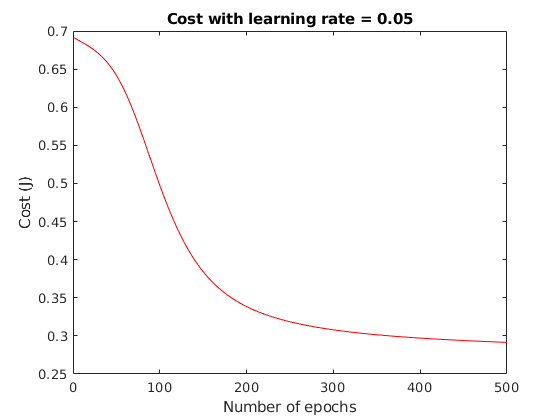

LossFunction = 'Log-Loss'; J = costFunction(Ytrain, ypred, LossFunction)

### Backward propagation

We went over the derivative terms for a single step of back propagation, and the computation from the outer layer to the hidden layer will be the same:

#### 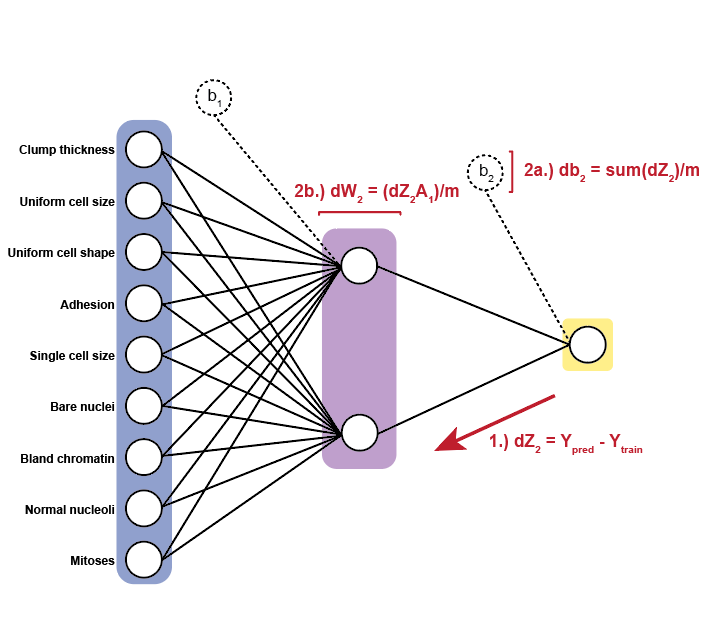

#### **Output layer to hidden layer**

- 
$$\textrm{dZ2}=Y_{\textrm{pred}} -Y_{\textrm{train}} \;$$


- 
$$d\mathrm{W2}=\mathrm{dZ2}\cdot {\mathrm{A1}}^T \cdot \frac{1}{m}$$


- 
$$\;\mathrm{db2}=\;\mathrm{db1}=\frac{1}{m}\sum_{i=1}^n \left(\mathrm{dZ2}\right)$$


First let's compute the error from the output $\textrm{dZ2}=Y_{\textrm{pred}} -Y_{\textrm{train}}$

dZ2 = ypred - Ytrain

Next, we have to compute how much error our weights contributed to the overall error in proportion to `dZ.` $\frac{1}{m}$ normalizes our error term by the number of observations in the dataset: $d\textrm{W2}=\frac{1}{m}\left(\textrm{dZ}\cdot {\textrm{A1}}^T \right)$

m = size(Xtrain, 1) % m = number of observations in training set
dW2 = (1/m) .* (A1' * dZ2)

Finally, we compute the error in the bias term, which is the sum of the errors from the output layer normalized based on the number of observations in the data: 


$$\;\textrm{db2}=$$
 
$$\frac{1}{m}\sum_{i=1}^n \left(\textrm{dZ2}\right)$$
 

db2  = (1/m) .* sum(dZ2, 2)

#### **Hidden layer to input layer**

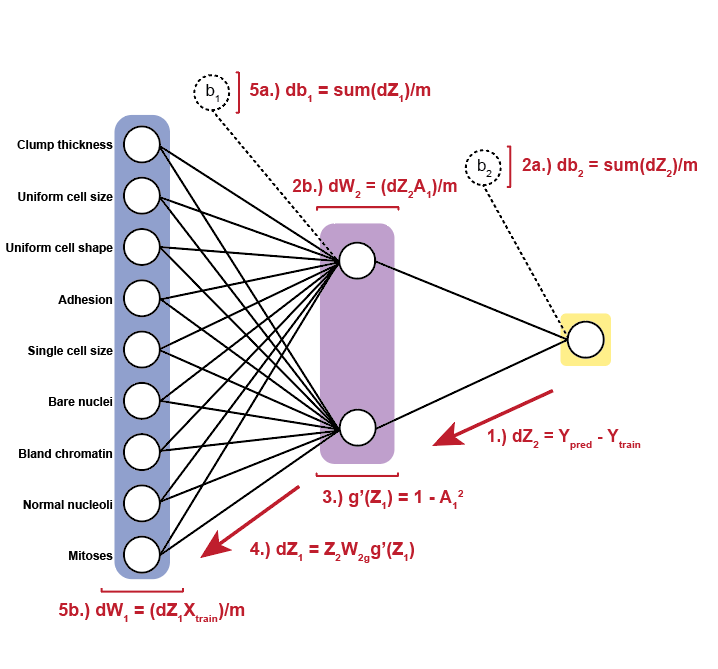

The computation for the hidden layer to the input layer will essentially be the same, except for computing `dZ1.` This time, we need to compute the error generated from the activation function, `g'(Z1)`:

- $g^{\prime } \left(\textrm{Z1}\right)\;=\left(1-{\textrm{A1}}^2 \right)$.

- 
$$\textrm{dZ1}={\textrm{W2}}^T \cdot \textrm{Z2}\cdot g^{\prime } \left(\textrm{Z1}\right)$$


- 
$$d\textrm{W1}=\frac{1}{m}\left(\textrm{dZ1}\cdot {X_{\textrm{train}} }^T \right)$$


- 
$$\;\textrm{db1}=\frac{1}{m}\sum_{i=1}^n \left(\textrm{dZ1}\right)$$


As noted earlier, the activation function does have its own error term $g^{\prime } \left(\textrm{Z1}\right)$. For the sigmoid activation function derivative term: $g^{\prime } \left(\textrm{Z1}\right)\;=\left(1-{\textrm{A1}}^2 \right)$. 

However, the ReLU and leaky ReLU are nice in that there is no derivative! Instead, we can use the following rule sets:


$${g^{\prime } \left(Z\right)}_{\textrm{ReLU}} =\left\lbrace \begin{array}{cc}
1 & \textrm{if}\;Z>0\\
0 & \textrm{if}\;Z\le 0
\end{array}\right.$$



$${g^{\prime } \left(Z\right)}_{\textrm{Leaky}\;\textrm{ReLU}} =\left\lbrace \begin{array}{cc}
1 & \textrm{if}\;Z>0\\
\varepsilon  & \textrm{if}\;Z\le 0
\end{array}\right.$$


Let's repeat the final step of back propagation, using the sigmoid activation function gradient: $\textrm{dZ1}={\textrm{W2}}^T \cdot \textrm{Z2}\cdot g^{\prime } \left(\textrm{Z1}\right)$

dZ1  = (w2 * dZ2') .* (1 - A1.^2)'

Next, let's compute dW1: $\frac{1}{m}\left(\textrm{dZ1}\cdot {X_{\textrm{train}} }^T \right)$

dW1  = (1/m) .* Xtrain' * dZ1'

Finally, we need to compute the cost for the biases: $\;\textrm{db1}=\frac{1}{m}\sum_{i=1}^n \left(\textrm{dZ1}\right)$

db1  = (1/m) .* sum(dZ1', 2)

### Gradient descent

Now that we computed the gradients, let's compute the updated weights and biases using gradient descent:

learning_rate = 0.05;
w2 = w2 - (learning_rate .* dW2)
b2 = b2 - (learning_rate .* db2)
w1 = w1 - (learning_rate .* dW1)
b1 = b1 - (learning_rate .* db1)

## Optimizing the neural network for binary classification

Now that we have all the steps required to train, evaluate, and optimize a shallow neural network, we would iterate this until the cost value reaches a minimum. 

To review, the model architecture we have constructed is shown below, along with the computations for a single forward and backward pass. Now we will iterate this computation for 500 epochs. 

To save space for iteratively running the shallow neural network we just wrote, we created an accessory function `SNN.` It has modularized the three steps we previously performed: forward propagation, evaluating the cost, and back propagation. The docstring is provided below:

### Training and optimizing the shallow neural network

Let's now use this function to train a neural network using the cancer dataset:

% Specify hyperparameters to train the model and store in structure
hyperparameters.numOfActiveNodes = 2;   hyperparameters.alpha = 0.05;

cleveland = 303×14 table
    Age    SEX    chestPain    restingBP    cholest    highBloodSugar    ECG    maxHR    angina0    ECGDepression    slopeST    flouroscopy    thalliumTest    diseaseSeverity
    ___    ___    _________    _________    _______    ______________    ___    _____    _______    _____________    _______    ___________    ____________    _______________

    63      1         1           145         233            1            2      150        0            2.3            3            0              

hyperparameters.epoch            = 500; hyperparameters.actFnc = 'Sigmoid';
hyperparameters.randomstate      = 2;

% Train the shallow neural network model
model = SNN(Xtrain, Ytrain, hyperparameters)

### Evaluating the costs

Now that we have a trained model, let's evaluate the results. First, let's plot the cost with respect to the number of iterations we made in the model:

figure; epoch = 500;
plot(1:epoch, model.J, 'color', 'r');
title('Cost with learning rate = 0.05');
xlabel('Number of epochs'); ylabel('Cost (J)');
saveas(gcf, 'SNNJCurve.fig')

### Benchmarking the shallow neural network using 5-fold cross validation

We'll benchmark our shallow neural network using the hyperparameters from the random grid search. We'll perform 5-fold cross validation, and compare our results against the logistic regression classifier.

% Neural network 5-fold cross validation
kfold = 5; type = 'SNN';
trainingSize = 0.8; randomState = 2;
nnCM = crossValidate(Xtrain, Ytrain, Xtest, Ytest, ...
                            hyperparameters, kfold, type)
% Show results from logistic regression cross validation 
load logisticRegressionResults.mat
logRegressCV
% Load the logistic regression cross validation confusion matrix
openfig('logRegressCM.fig', 'visible')
title('Confusion matrix from logistic regression 5-fold cross validation');
labels = {'Malignant', 'Benign'};

### Plot the neural network confusion matrix from 5-fold cross validation and benchmark against logistic regression 

cm = nnCM.cm;
confusionchart(cm, labels);
title('Confusion matrix from neural network 5-fold cross validation');
TP  = cm(1, 1); FP = cm(1, 2); FN = cm(2, 1); TN  = cm(2, 2);
malignant_precision = (TP) / (TP + FP)
malignant_recall    = (TP) / (TP + FN)
benign_precision    = (TN) / (TN + FP)
benign_recall       = (TN) / (TN + FN)
average_accuracy    = sum(diag(cm)) / sum(cm, 'all')

We are able to show that the neural network beats the logistic regression classifier. 

Now that we have demonstrated how neural networks operate under the hood, let's discuss how to use the built-in tools MATLAB provides not only for shallow neural networks, but for extending our computations to deep neural networks.

## Neural Networks for k-class classification problems

Now that we have seen how a shallow neural network works with a binary classification problem, let's extend our approach to a k-class classification problem to the Cleveland heart disease dataset. 

### Load the cleveland dataset

Recall that the dataset has 5 different classes for disease heart disease severity, where 0 is no disease and 4 is high risk. 

clear all; cleveland = readtable('cleveland.xlsx')

First, we need to split the dataset into a training and testing set.

% Initialize params for trainTestSplit

Ytrain =      1     0     0     0     0
     0     0     1     0     0
     0     1     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     0     0     0     1     0
     0     1     0     0     0
     1     0     0     0     0
     1     0     0     0     0


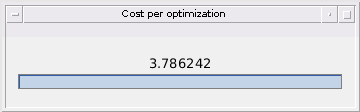

model = struct with fields:
     ypred: [242×5 double]
         J: [500×5 double]
        w2: [10×5 double]
        b2: [242×1 double]
        w1: [13×10 double]
        b1: [242×1 double]
    actFnc: 'Softmax'


trainingSize = 0.8; randomstate = 2;

% Split the dataset into training and test sets.
[Xtrain, Ytrain, Xtest, Ytest] = ...
    trainTestSplit(cleveland(:, 1:end-1), cleveland(:, end), ...
    trainingSize, randomstate);

% Standardize the dataset with mean = 0 and standard deviation = 1. 
mu = mean(Xtrain); sigma = std(Xtrain);

Xtrain = (Xtrain - mu) ./ sigma; 

ypred =     0.0010    0.0163    0.0164    0.0164    0.0164
    0.0010    0.0163    0.0164    0.0164    0.0164
    0.0010    0.0163    0.0164    0.0164    0.0164
    0.0010    0.0163    0.0164    0.0164    0.0164
    0.0010    0.0163    0.0164    0.0164    0.0164
    0.0010    0.0163    0.0164    0.0164    0.0164
    0.0010    0.0163    0.0164    0.0164    0.0164
    0.0010    0.0163    0.0164    0.0164    0.0164
    0.0010    0.0163    0.0164    0.0164    0.0164
    0.0010    0.0163    0.0164    0.0164    0.0164


Xtest  = (Xtest - mu)  ./ sigma; % Use the same mu and sigma -> assume same distribution

### Initialize model hyperparameters

Next, let's initialize hyperparameters.

% Specify hyperparameters to train the model and store in structure
hyperparameters.numOfActiveNodes = 10;  hyperparameters.alpha = 0.05;
hyperparameters.epoch            = 500; hyperparameters.actFnc = 'Softmax';
hyperparameters.randomstate      = 2;

Before we train the model, we need to make some minor adjustments to the way we've been computing our probabilities in the activation function:

### The softmax activation function

#### Intuition of the softmax activation function

The sigmoid activation function expression simply transforms values into probabilities using the following expression:$A=\frac{1}{1+e^{-Z} }$

If Z is very large, the expression moves towards 1, while if Z is very small, the expression moves towards 0. This allows us to transform values to assume a binary distribution, and gives us a natural decision boundary: $p=0\ldotp 5$. The question now then, is how do we draw multiple decision boundaries for a k-class problem?

One method is to label encode an $n\times k$ response array, where each column corresponds to a $k$ target variable. Each element in the array assumes a binary value [0, 1] that corresponds to whether the observation is labeled as that $k^{\textrm{th}}$ class (1), or it not (0). A schematic of this label encoding scheme is shown below:

Let's label encode our $Y_{\textrm{train}}$ and $Y_{\textrm{test}}$ so that each column corresponds to whether the disease severity belongs to either a score of 0, 1, 2, 3, or 4.

% Initialize our arrays. Because there are 5 classes, we need to make an n
% x 5 array
kclasses = length(unique(Ytest));
tmpYtrain = zeros(size(Ytrain, 1), kclasses);
tmpYtest = zeros(size(Ytest, 1), kclasses);

% Make new response arrays. Note that the classes are between 0 and 4.
for i = 1:kclasses
    tmpYtrain(:, i) = (Ytrain == (i - 1));
    tmpYtest(:, i) = (Ytest == (i - 1));
end
Ytrain = tmpYtrain; Ytest = tmpYtest;
Ytrain % Show only Ytrain

 Now that we have each class in its own vector, we can use the generalized form of the sigmoid activation function, known as the **softmax activation function.** 

The formulation normalizes the probability of that observation belonging to class $k$ over the proportion of all observations that may be in class $k$: 

$A=\frac{e^{Z_k } }{\underset{k}{\sum e^{Z_k } } }$ where $k$ denotes a specific class. 

### Training the k-class shallow neural network

Let's now run our k-class classification problem using the shallow neural network we constructed.

% Train the shallow neural network model
model = SNN(Xtrain, Ytrain, hyperparameters)
ypred = mdlPredict(model, Xtest, 'SNN')

## Neural Networks for regression

Let's now apply a shallow neural network to a regression problem, where we will use the entire glioblastoma dataset to predict the survival rate (`SurvivalDaysOS)` for 12 out of the 60 patients (20% of the dataset).

clear all; load gbm.mat
X
Y
% Initialize params for trainTestSplit
trainingSize = 0.8; randomstate = 2;

% Split the dataset into training and test sets.
[Xtrain, Ytrain, Xtest, Ytest] = trainTestSplit(X, Y, trainingSize, randomstate);

% Standardize the dataset with mean = 0 and standard deviation = 1. 
mu = mean(Xtrain); sigma = std(Xtrain);
Xtrain = (Xtrain - mu) ./ sigma; 
Xtest  = (Xtest - mu)  ./ sigma; % Use the same mu and sigma -> assume same distribution

We will perform the same computations as we have previously. However, we need to change our algorithm by making the following changes:

- We don't compute transform the values into probabilities from the hidden layer to the output layer. Instead, we should use the **ReLU** or **leaky ReLU** activation functions.

- To evaluate the cost error, we can use the **mean-squared error** loss function to compute the distance between the predicted and training value. 

## Summary

We constructed a shallow neural network from scratch and benchmarked a logistic regression classifier against the shallow neural network using the breast cancer imaging dataset. We then applied our shallow neural network to a k-class classification problem and regression. 

In the next lecture, we will use MATLAB's Deep Learning Toolbox to train a shallow neural network,  and deep neural network.

### Built-in MATLAB functions

`confusionmat:             `Automatically computes a confusion matrix for each class.

`confusionchart`:                         Plots the confusion matrix from `confusionmat`

### Custom MATLAB functions

`trainTestSplit:           `Splits an input ($X$) and output ($Y$) dataset into a training $\left(X_{\textrm{train}} {,\;Y}_{\textrm{train}} \right)$ and testing $\left(X_{\textrm{test}} {,\;Y}_{\textrm{test}} \right)$ dataset

`activationFnc:            `Transforms the dataset using a non-linear function.

`costFunction:`                            Computes the cost value from the model.

`crossValidate:`                          Performs k-fold cross validation.

`SNN:`                                               Trains a shallow neural network.